close all
clear
clc

figure(1);

拖动控件改变极点角度，从-pi到pi/2

theta_array = pi+1E-5:-pi/50:pi/2+1E-5;
id = 4;
theta = theta_array(id);

按角度生成极点实部绝对值alpha

omega0 = 1;
alpha = omega0 * -cos(theta);

绘制零极点图

subplot(2,2,1);
b = [1,0];
a = [1,2*alpha,omega0^2];
pzmap(b,a);
set(gca,'XLim',[-1.5,0.5],'YLim',[-1.5,1.5]);

绘制冲激响应

[h,x,t] = impulse(b,a,[0:0.1:30]);
subplot(2,2,3);
plot(t,h);
set(gca,'XLim',[0,30],'YLim',[-2,2]);

计算频率响应

[H,w] = freqs(b,a,[0.01:0.01:100]);

绘制幅频

subplot(2,2,2);
plot(w,abs(H));
set(gca,'XLim',[0.01,100],'YLim',[0.01,10],'YScale','log','XScale','log');
grid on;

绘制相频

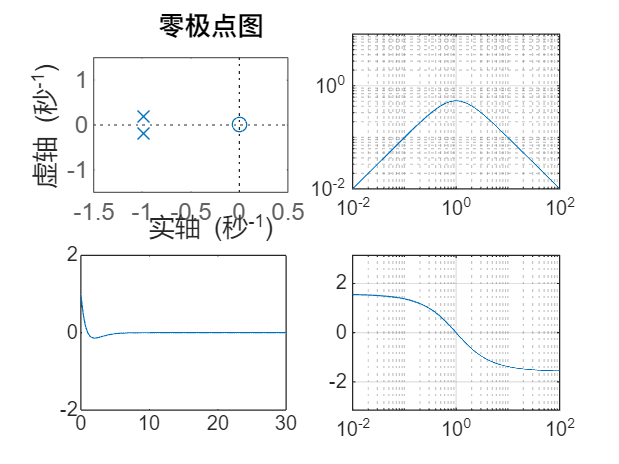

subplot(2,2,4);
plot(w,angle(H));
set(gca,'XLim',[0.01,100],'YLim',[-pi,pi],'XScale','log');
grid on;